Colin Keenan

ECE 5470

4-20-2020

# Homework 10

1.  Opening and Closing

## Fingerprint 1

clear

fprintf("Question 1, Fingerprint 1:")

Question 1, Fingerprint 1:

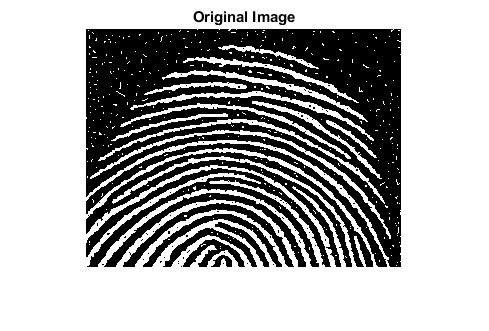


image = im2double(imread('Fig6-1a.tif'));

struct_1 = [[0 1 0]
            [1 1 1]
            [0 1 0]];
        
struct_2 = [[1 1 1]
            [1 1 1]
            [1 1 1]];

% Opening: Erosion, then Dilation
opened_1 = open(image, struct_1);
opened_2 = open(image, struct_2);

% Closing: Dilation, then Erosion
closed_1 = close(image, struct_1);
closed_2 = close(image, struct_2);

figure();
imshow(image);
title('Original Image');

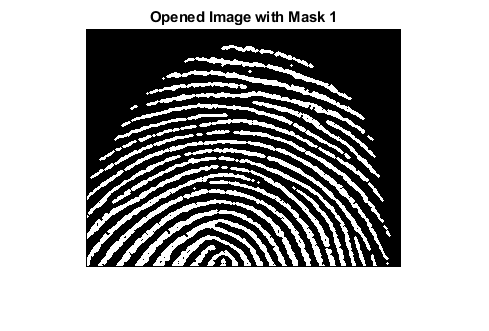

figure();
imshow(opened_1);
title('Opened Image with Mask 1');

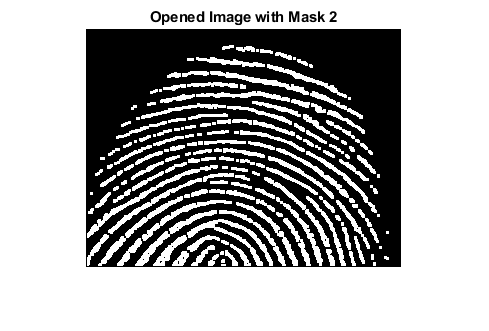

figure();
imshow(opened_2);
title('Opened Image with Mask 2');

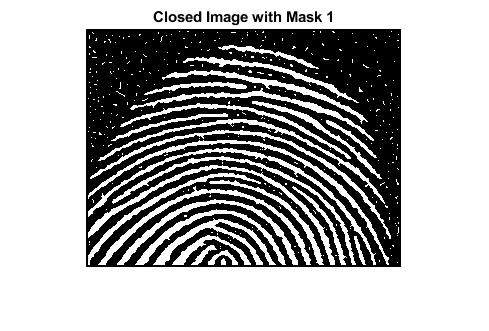

figure();
imshow(closed_1);
title('Closed Image with Mask 1');

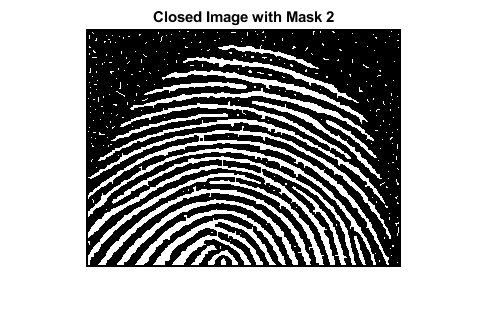

figure();
imshow(closed_2);
title('Closed Image with Mask 2');

## Fingerprint 2

clear

fprintf("Question 1, Fingerprint 2:")

Question 1, Fingerprint 2:

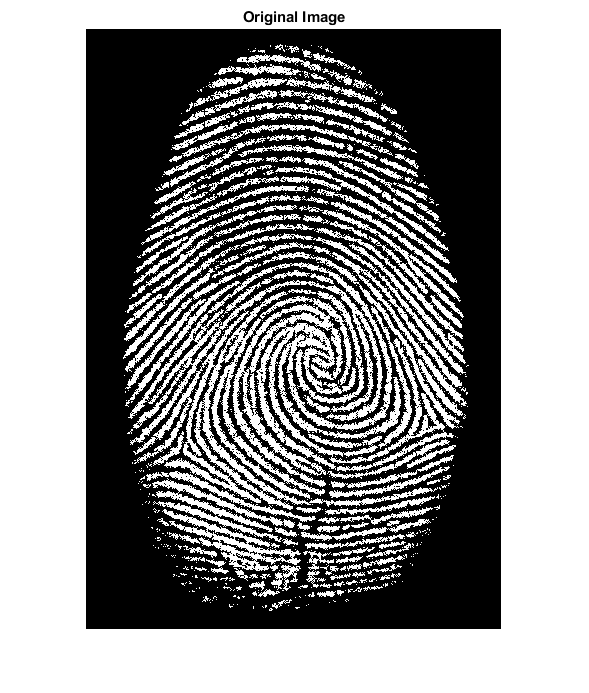


image = im2double(imread('Fig6-1b.tif'));

struct_1 = [[0 1 0]
            [1 1 1]
            [0 1 0]];
        
struct_2 = [[1 1 1]
            [1 1 1]
            [1 1 1]];

% Opening: Erosion, then Dilation
opened_1 = open(image, struct_1);
opened_2 = open(image, struct_2);

% Closing: Dilation, then Erosion
closed_1 = close(image, struct_1);
closed_2 = close(image, struct_2);

figure();
imshow(image);
title('Original Image');

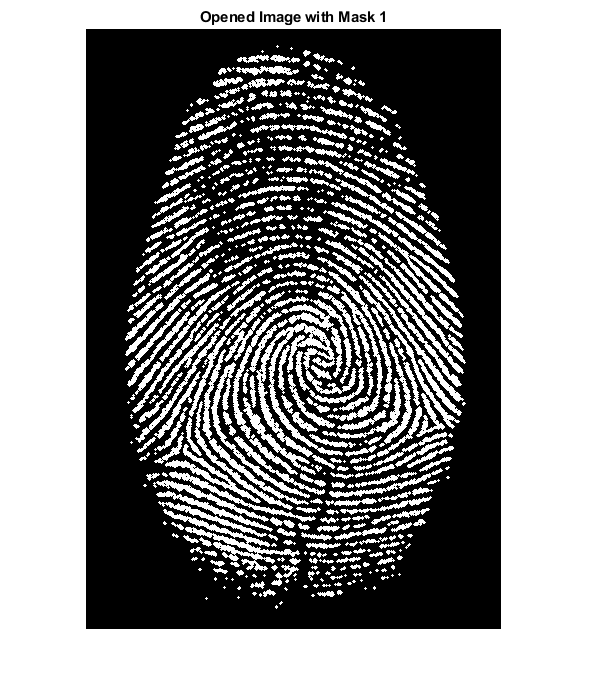

figure();
imshow(opened_1);
title('Opened Image with Mask 1');

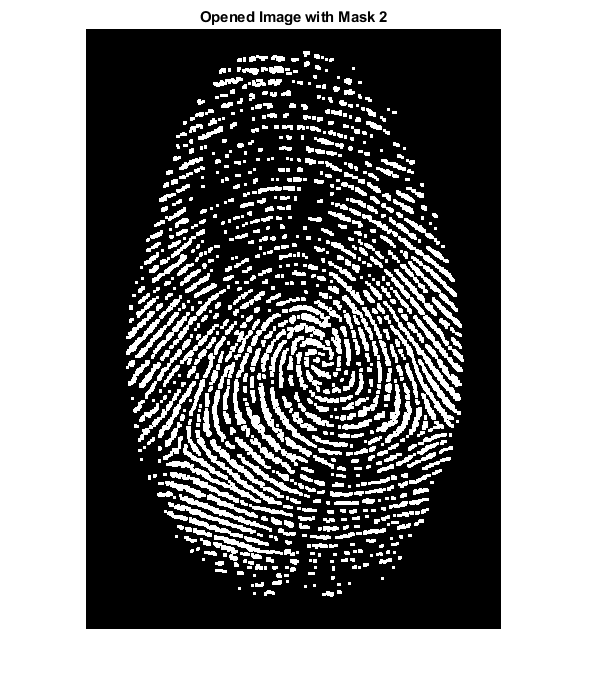

figure();
imshow(opened_2);
title('Opened Image with Mask 2');

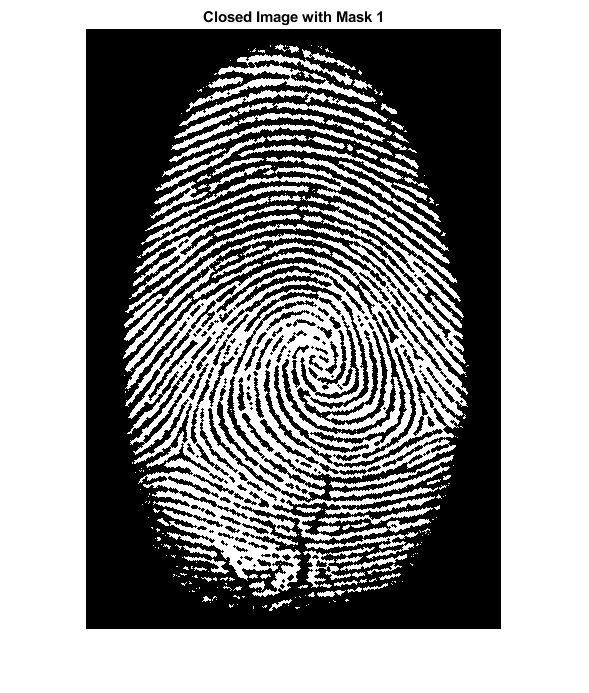

figure();
imshow(closed_1);
title('Closed Image with Mask 1');

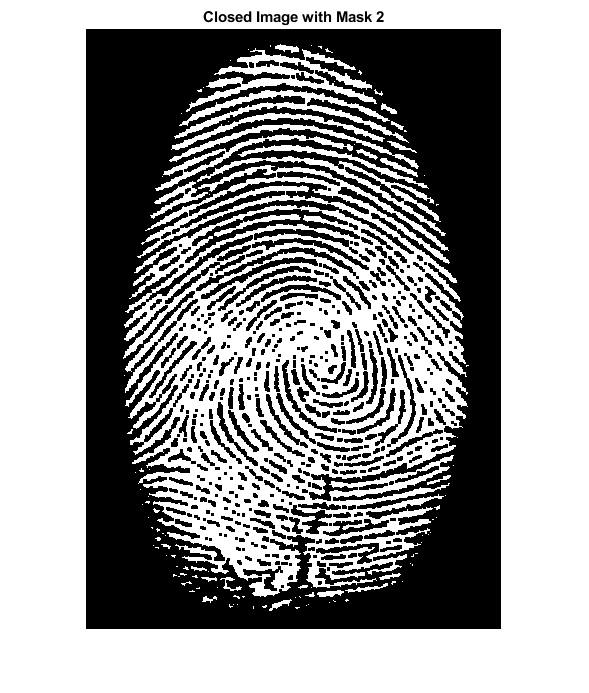

figure();
imshow(closed_2);
title('Closed Image with Mask 2');

## Appendix (Functions Used)

function eroded = erode(image, struct)
    eroded = zeros(size(image));
    frame = zeros(size(struct));
    pad = floor(size(struct,1)/2);

    for i = 1+pad : size(image,1)-pad
        for j = 1+pad : size(image,2)-pad
            
            % Get Current Frame
            xOffset = -1*pad-1;   
            for x = 1:size(frame,1)
                yOffset = -1*pad;
                xOffset = xOffset + 1;
                for y = 1:size(frame,2)
                    frame(x,y) = image(i+xOffset,j+yOffset);
                    yOffset = yOffset + 1;
                end
            end
            
%             frame = [[image(i-1,j-1) image(i-1,j+0) image(i-1,j+1)]
%                      [image(i+0,j-1) image(i+0,j+0) image(i+0,j+1)]
%                      [image(i+1,j-1) image(i+1,j+0) image(i+1,j+1)]];
            
            if((frame & struct) == struct)
                eroded(i,j) = 1;
            else
                eroded(i,j) = 0;
            end
        end
    end
end

function dilated = dilate(image, struct)
    dilated = zeros(size(image));
    frame = zeros(size(struct));
    pad = floor(size(struct,1)/2);
    
    for i = 1+pad : size(image,1)-pad
        for j = 1+pad : size(image,2)-pad
            
            % Get Current Frame
            xOffset = -1*pad-1;   
            for x = 1:size(frame,1)
                yOffset = -1*pad;
                xOffset = xOffset + 1;
                for y = 1:size(frame,2)
                    frame(x,y) = image(i+xOffset,j+yOffset);
                    yOffset = yOffset + 1;
                end
            end
            
%             frame = [[image(i-1,j-1) image(i-1,j+0) image(i-1,j+1)]
%                      [image(i+0,j-1) image(i+0,j+0) image(i+0,j+1)]
%                      [image(i+1,j-1) image(i+1,j+0) image(i+1,j+1)]];
            
            if((frame & struct) == 0)
                dilated(i,j) = 0;
            else
                dilated(i,j) = 1;
            end
       
        end
    end
end

function opened = open(image,struct)
    eroded = erode(image,struct);
    opened = dilate(eroded,struct);
end

function closed = close(image,struct)
    dilated = dilate(image,struct);
    closed = erode(dilated,struct);
end